# Load Data

load 'ftData_50b.mat';
load 'ftData.mat';
load 'GM_pow_wplid.mat';
restoredefaultpath;
clear RESTOREDEFAULTPATH_EXECUTED;
addpath('/Users/rejoel/Library/Application Support/MathWorks/MATLAB Add-Ons/Collections/FieldTrip/');
ft_defaults;

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

## Power  Spectrum Computation

cfg           = [];
cfg.method    = 'mtmfft';
cfg.taper     = 'dpss';
cfg.output    = 'pow';
cfg.tapsmofrq = 2;
cfg.pad       = 'nextpow2';

GM_powspctrm_cov = [];
for i=1:length(ftData_cov)
    freq_pow_temp = ft_freqanalysis(cfg, ftData_cov{i});
    GM_powspctrm_cov(i,:,:) = freq_pow_temp.powspctrm;    
end

the input is raw data with 18 channels and 52 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 52/52 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 1 seconds and required the additional allocation of an estimated NaN MB
the input is raw data with 18 channels and 52 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 52/52 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB
the input is raw data with 18 channels and 58 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 58/58 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqa


GM_powspctrm_longcov=[];
for i=1:length(ftData_longcov)
    freq_pow_temp = ft_freqanalysis(cfg, ftData_longcov{i});
    GM_powspctrm_longcov(i,:,:) = freq_pow_temp.powspctrm;
end

the input is raw data with 18 channels and 45 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 45/45 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB
the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB
the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqa


GM_powspctrm_longcov1=[];
for i=1:length(ftData_longcov1)
    freq_pow_temp = ft_freqanalysis(cfg, ftData_longcov1{i});
    GM_powspctrm_longcov1(i,:,:) = freq_pow_temp.powspctrm;
end

the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB
the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB
the input is raw data with 18 channels and 49 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 49/49 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqa


GM_powspctrm_longcov2=[];
for i=1:length(ftData_longcov2)
    freq_pow_temp = ft_freqanalysis(cfg, ftData_longcov2{i});
    GM_powspctrm_longcov2(i,:,:) = freq_pow_temp.powspctrm;
end

the input is raw data with 18 channels and 45 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 45/45 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB
the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB
the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqa

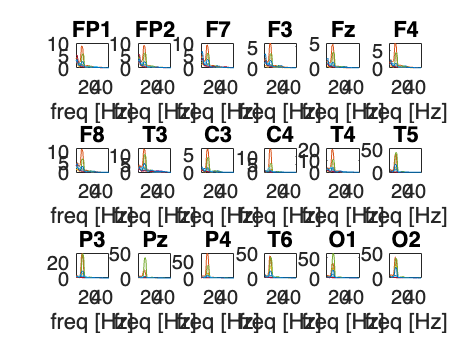


freq = freq_pow_temp.freq;
label = freq_pow_temp.label;
 
figure
for i=1:18
    subplot(3,6,i)
    %plot(freq,squeeze(mean(GM_powspctrm_cov(:,i,:))))
    plot(freq,squeeze(GM_powspctrm_cov(:,i,:)))
    title(label{i}); 
    xlim([1 50]); 
    %ylim([0 max(GM_powspctrm_cov(:))])
    xlabel('freq [Hz]')
end

## Plot PSD

figure
for i=1:18
    subplot(3,6,i)
    %plot(freq,squeeze(mean(GM_powspctrm_cov(:,i,:))))
    plot(freq,squeeze(GM_powspctrm_cov(:,i,:)))
    title(label{i}); 
    xlim([1 50]); 
    %ylim([0 max(GM_powspctrm_cov(:))])
    xlabel('freq [Hz]')
end

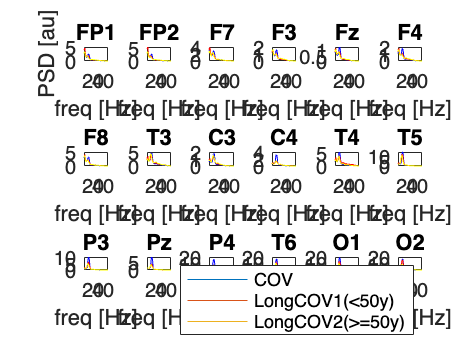


figure
for i=1:18
    subplot(3,6,i)
    plot(freq,squeeze(mean(GM_powspctrm_cov(:,i,:)))); hold on
    plot(freq,squeeze(mean(GM_powspctrm_longcov1(:,i,:))));
    plot(freq,squeeze(mean(GM_powspctrm_longcov2(:,i,:)))); 
    plot(freq,squeeze(mean(GM_powspctrm_cov(:,i,:))),'b');
    plot(freq,squeeze(mean(GM_powspctrm_longcov1(:,i,:))),'r');
    plot(freq,squeeze(mean(GM_powspctrm_longcov2(:,i,:))),'y');
    hold off
    if i==1, ylabel('PSD [au]'); end
    title(label{i}); 
    xlim([1 50]); 
    %ylim([0 max(GM_powspctrm_cov(:))])
    xlabel('freq [Hz]')    
end

%spctrmBL{ityp,nfield}=nanmean(dataspctrmBL{ityp,nfield});
%spctrmBLerf{ityp,nfield}=nanstd(dataspctrmBL{ityp,nfield})/sqrt(length(dataspctrmBL{ityp,nfield}));

lgd = legend('COV','LongCOV1(<50y)', 'LongCOV2(>=50y)');


freq_ind = interp1(freq,1:length(freq),10, 'nearest'); % at 10 Hz

f_delta_ind = interp1(freq,1:length(freq), 2, 'nearest');
f_theta_ind = interp1(freq,1:length(freq), 4, 'nearest');
f_alpha_ind = interp1(freq,1:length(freq), 10, 'nearest');
f_beta_ind  = interp1(freq,1:length(freq), 20, 'nearest');
f_gamma_ind = interp1(freq,1:length(freq), 40, 'nearest');

PSD = [];
for i=1:18
    [PSD.p(i,1),PSD.h(i,1),PSD.stat(i,1)]=ranksum(squeeze(GM_powspctrm_cov(:,i,f_delta_ind)), squeeze(GM_powspctrm_longcov(:,i,f_delta_ind)))
    [PSD.p(i,2),PSD.h(i,2),PSD.stat(i,2)]=ranksum(squeeze(GM_powspctrm_cov(:,i,f_theta_ind)), squeeze(GM_powspctrm_longcov(:,i,f_theta_ind)))
    [PSD.p(i,3),PSD.h(i,3),PSD.stat(i,3)]=ranksum(squeeze(GM_powspctrm_cov(:,i,f_alpha_ind)), squeeze(GM_powspctrm_longcov(:,i,f_alpha_ind)))
    [PSD.p(i,4),PSD.h(i,4),PSD.stat(i,4)]=ranksum(squeeze(GM_powspctrm_cov(:,i,f_beta_ind)), squeeze(GM_powspctrm_longcov(:,i,f_beta_ind)))
    [PSD.p(i,5),PSD.h(i,5),PSD.stat(i,5)]=ranksum(squeeze(GM_powspctrm_cov(:,i,f_gamma_ind)), squeeze(GM_powspctrm_longcov(:,i,f_gamma_ind)))
end

PSD = struct with fields:
       p: 0.6239
       h: 0
    stat: [1×1 struct]


PSD = struct with fields:
       p: 0.6239
       h: 0
    stat: [1×1 struct]


PSD = struct with fields:
       p: 0.6239
       h: 0
    stat: [1×1 struct]


PSD = struct with fields:
       p: [0.6239 0.4268]
       h: [0 0]
    stat: [1×2 struct]


PSD = struct with fields:
       p: [0.6239 0.4268]
       h: [0 0]
    stat: [1×2 struct]


PSD = struct with fields:
       p: [0.6239 0.4268]
       h: [0 0]
    stat: [1×2 struct]


PSD = struct with fields:
       p: [0.6239 0.4268 0.9595]
       h: [0 0 0]
    stat: [1×3 struct]


PSD = struct with fields:
       p: [0.6239 0.4268 0.9595]
       h: [0 0 0]
    stat: [1×3 struct]


PSD = struct with fields:
       p: [0.6239 0.4268 0.9595]
       h: [0 0 0]
    stat: [1×3 struct]


PSD = struct with fields:
       p: [0.6239 0.4268 0.9595 0.3024]
       h: [0 0 0 0]
    stat: [1×4 struct]


PSD = struct with fields:
       p: [0.6239 0.4268 0.9595 0.3024]
       h: [0 0 0 0]
    stat: [1×4 struct]


PSD = struct with fields:
       p: [0.6239 0.4268 0.9595 0.3024]
       h: [0 0 0 0]
    stat: [1×4 struct]


PSD = struct with fields:
       p: [0.6239 0.4268 0.9595 0.3024 0.1930]
       h: [0 0 0 0 0]
    stat: [1×5 struct]


PSD = struct with fields:
       p: [0.6239 0.4268 0.9595 0.3024 0.1930]
       h: [0 0 0 0 0]
    stat: [1×5 struct]


PSD = struct with fields:
       p: [0.6239 0.4268 0.9595 0.3024 0.1930]
       h: [0 0 0 0 0]
    stat: [1×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [2×5 double]
       h: [2×5 logical]
    stat: [2×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [3×5 double]
       h: [3×5 logical]
    stat: [3×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [4×5 double]
       h: [4×5 logical]
    stat: [4×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [5×5 double]
       h: [5×5 logical]
    stat: [5×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [6×5 double]
       h: [6×5 logical]
    stat: [6×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [7×5 double]
       h: [7×5 logical]
    stat: [7×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [8×5 double]
       h: [8×5 logical]
    stat: [8×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [9×5 double]
       h: [9×5 logical]
    stat: [9×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [10×5 double]
       h: [10×5 logical]
    stat: [10×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [11×5 double]
       h: [11×5 logical]
    stat: [11×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [12×5 double]
       h: [12×5 logical]
    stat: [12×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [13×5 double]
       h: [13×5 logical]
    stat: [13×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [14×5 double]
       h: [14×5 logical]
    stat: [14×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [15×5 double]
       h: [15×5 logical]
    stat: [15×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [16×5 double]
       h: [16×5 logical]
    stat: [16×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [17×5 double]
       h: [17×5 logical]
    stat: [17×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


PSD = struct with fields:
       p: [18×5 double]
       h: [18×5 logical]
    stat: [18×5 struct]


## Connectivity Analysis

GM_wplid_cov = [];
for i=1:length(ftData_cov)
    cfg           = [];
    cfg.method    = 'mtmfft';
    cfg.taper     = 'dpss';
    cfg.output    = 'fourier';
    cfg.tapsmofrq = 2;
    cfg.pad       = 'nextpow2';
    fourier_temp  = ft_freqanalysis(cfg, ftData_cov{i});

    cfg           = [];
    cfg.method    = 'wpli_debiased';
    wplid_temp    = ft_connectivityanalysis(cfg, fourier_temp);

    GM_wplid_cov(i,:,:,:) = wplid_temp.wpli_debiasedspctrm;
end

the input is raw data with 18 channels and 52 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 52/52 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 52 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 52/52 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 58 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 58/58 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 57 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 57/57 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 56 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 56/56 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 58 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 58/58 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB



GM_wplid_longcov = [];
for i=1:length(ftData_longcov)
    cfg           = [];
    cfg.method    = 'mtmfft';
    cfg.taper     = 'dpss';
    cfg.output    = 'fourier';
    cfg.tapsmofrq = 2;
    cfg.pad       = 'nextpow2';
    fourier_temp  = ft_freqanalysis(cfg, ftData_longcov{i});

    cfg           = [];
    cfg.method    = 'wpli_debiased';
    wplid_temp    = ft_connectivityanalysis(cfg, fourier_temp);

    GM_wplid_longcov(i,:,:,:) = wplid_temp.wpli_debiasedspctrm;
end

the input is raw data with 18 channels and 45 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 45/45 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 49 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 49/49 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 52 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 52/52 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 49 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 49/49 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 44 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 44/44 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 53 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 53/53 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 53 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 53/53 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 48 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 48/48 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 48 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 48/48 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 48 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 48/48 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 53 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 53/53 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 53 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 53/53 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 43 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 43/43 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 53 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 53/53 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 51 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 51/51 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 53 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 53/53 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 52 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 52/52 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 42 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 42/42 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 52 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 52/52 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 40 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 40/40 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB



GM_wplid_longcov1 = [];
for i=1:length(ftData_longcov1)
    cfg           = [];
    cfg.method    = 'mtmfft';
    cfg.taper     = 'dpss';
    cfg.output    = 'fourier';
    cfg.tapsmofrq = 2;
    cfg.pad       = 'nextpow2';
    fourier_temp  = ft_freqanalysis(cfg, ftData_longcov1{i});

    cfg           = [];
    cfg.method    = 'wpli_debiased';
    wplid_temp    = ft_connectivityanalysis(cfg, fourier_temp);

    GM_wplid_longcov1(i,:,:,:) = wplid_temp.wpli_debiasedspctrm;
end

the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 49 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 49/49 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 52 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 52/52 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 49 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 49/49 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 44 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 44/44 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 53 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 53/53 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 53 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 53/53 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 48 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 48/48 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 53 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 53/53 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 53 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 53/53 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 43 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 43/43 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 53 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 53/53 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 53 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 53/53 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 52 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 52/52 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 42 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 42/42 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 52 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 52/52 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 40 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 40/40 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB



GM_wplid_longcov2 = [];
for i=1:length(ftData_longcov2)
    cfg           = [];
    cfg.method    = 'mtmfft';
    cfg.taper     = 'dpss';
    cfg.output    = 'fourier';
    cfg.tapsmofrq = 2;
    cfg.pad       = 'nextpow2';
    fourier_temp  = ft_freqanalysis(cfg, ftData_longcov2{i});

    cfg           = [];
    cfg.method    = 'wpli_debiased';
    wplid_temp    = ft_connectivityanalysis(cfg, fourier_temp);

    GM_wplid_longcov2(i,:,:,:) = wplid_temp.wpli_debiasedspctrm;
end

the input is raw data with 18 channels and 45 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 45/45 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 48 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 48/48 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 48 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 48/48 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 55 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 55/55 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 51 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 51/51 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the input is raw data with 18 channels and 54 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
processing trials
processing trial 54/54 nfft: 1023 samples, datalength: 1000 samples, 7 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


## Plot Connectivity Analysis


figure
n=1;
for i=1:18
    for j=1:18
        subplot(18,18,n)
        plot(freq,squeeze(mean(GM_wplid_cov(:,i,j,:)))); hold on
        plot(freq,squeeze(mean(GM_wplid_longcov1(:,i,j,:))));
        plot(freq,squeeze(mean(GM_wplid_longcov2(:,i,j,:)))); hold off
        if i==1, title(label{j}); end
        if j==1, ylabel(label{i}); end
        xlim([1 50]);
        ylim([0 0.4]);
        n=n+1;
    end
end
lgd = legend('COV','LongCOV1(<50y)', 'LongCOV2(>=50y)');


## Plot Connectivity Analysis Alpha

f_alpha_ind = 22;

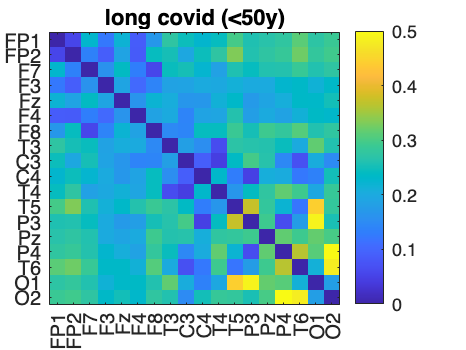

CON = [];
CON.p = nan(18,18); CON.h = nan(18,18); 
for i=1:18
    for j=1:18
        if i~=j
            [CON.p(i,j),CON.h(i,j),CON.stat(i,j)]=ranksum(squeeze(GM_wplid_cov(:,i,j,f_alpha_ind)), squeeze(GM_wplid_longcov(:,i,j,f_alpha_ind)));
        end
    end
end

CON1 = [];
CON1.p = nan(18,18); CON1.h = nan(18,18); 
for i=1:18
    for j=1:18
        if i~=j
            [CON1.p(i,j),CON1.h(i,j),CON1.stat(i,j)]=ranksum(squeeze(GM_wplid_longcov1(:,i,j,f_alpha_ind)), squeeze(GM_wplid_longcov2(:,i,j,f_alpha_ind)));
        end
    end
end

figure
imagesc(squeeze(mean(GM_wplid_cov(:,:,:,f_alpha_ind))))
colorbar
colormap parula
clim([0 0.5])
xticks(1:18); xticklabels(label)
yticks(1:18); yticklabels(label)
title('covid')

figure
imagesc(squeeze(mean(GM_wplid_longcov1(:,:,:,f_alpha_ind))))
colorbar
colormap parula
clim([0 0.5])
xticks(1:18); xticklabels(label)
yticks(1:18); yticklabels(label)
title('long covid (<50y)')

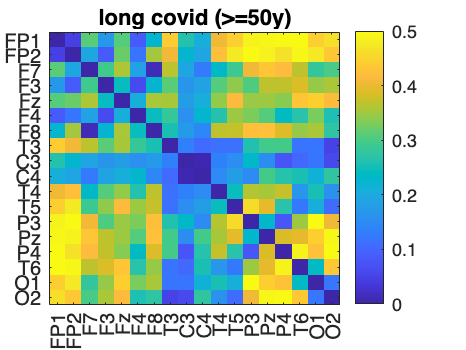


figure
imagesc(squeeze(mean(GM_wplid_longcov2(:,:,:,f_alpha_ind))))
colorbar
colormap parula
clim([0 0.5])
xticks(1:18); xticklabels(label)
yticks(1:18); yticklabels(label)
title('long covid (>=50y)')

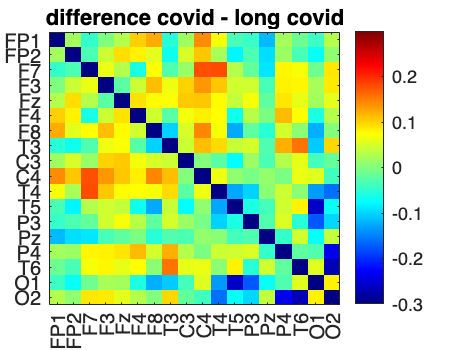


figure
GM_wplid_diff = squeeze(mean(GM_wplid_cov))-squeeze(mean(GM_wplid_longcov));
imagesc(squeeze(GM_wplid_diff(:,:,f_alpha_ind)))
colorbar
colormap jet
clim([-0.3 0.3])
xticks(1:18); xticklabels(label)
yticks(1:18); yticklabels(label)
title('difference covid - long covid')

## zval plot

zval_1 = zeros(length(labels), length(labels)); % Preallocate for efficiency
for chan1 = 1:length(labels)
    for chan2 = 1:length(labels)
        % Accessing zval for each pair of labels
        if ~isfield(CON.stat(chan1,chan2), 'zval')
            warning('zval field does not exist for (%d,%d)', chan1, chan2);
        end
        if isempty(CON.stat(chan1,chan2).zval)
            warning('zval is empty for (%d,%d)', chan1, chan2);
        end
        if isfield(CON.stat(chan1,chan2), 'zval') && ~isempty(CON.stat(chan1,chan2).zval)
            zval_1(chan1,chan2) = CON.stat(chan1,chan2).zval;
        end
    end
end



disp(CON.stat(2,1)); % Check if this exists and has a zval field

       zval: 0.0169
    ranksum: 165



disp(CON.stat(2,1).zval); % Check if zval has a value

    0.0169



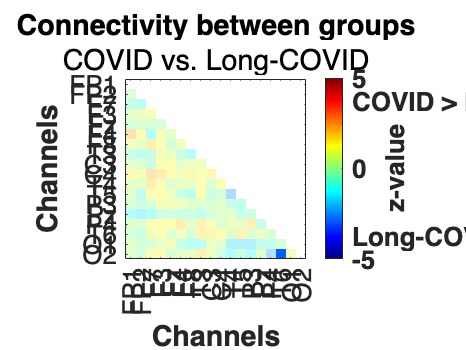


% cov vs. longcov
figure
zval_1(isnan(zval_1))=0;
alpha_array = (zval_1<-1.96) | (zval_1>1.96);
alpha_array_1 = 0.3*double(~alpha_array);
alpha_array_2 = double(alpha_array);
alpha_array = alpha_array_1 + alpha_array_2;
alpha_array = alpha_array - triu(alpha_array);

imagesc(zval_1,'AlphaData',alpha_array)
axis square
xlabel("Channels","FontSize",13,"FontWeight","bold"); ylabel("Channels","FontSize",13,"FontWeight","bold")
caxis([-3.92 3.92]);

colormap(jet)
c=colorbar();
c.Label.String = ["z-value"];
c.Label.Position(1) = 3;
c.FontSize = 13;
c.FontWeight= "bold";
c.Ticks = [-3.92,-2.94,-1.96, 0, 1.96, 2.94, 3.92];
c.TickLabels = [{int2str(-5),'Long-COVID > COVID','','0','','COVID > Long-COVID',int2str(5)}];

xticks(1:length(labels))
xticklabels(labels)     
yticks(1:length(labels))
yticklabels(labels)
title("Connectivity between groups")
subtitle("COVID vs. Long-COVID")
% subtitle("(dwPLI)","FontSize",13)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',13)

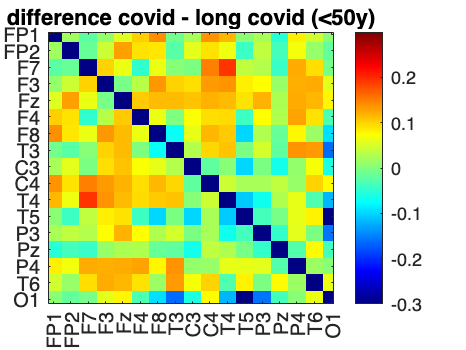

figure
GM_wplid_diff = squeeze(mean(GM_wplid_cov))-squeeze(mean(GM_wplid_longcov1));
imagesc(squeeze(GM_wplid_diff(:,:,f_alpha_ind)))
colorbar
colormap jet
clim([-0.3 0.3])
xticks(1:18); xticklabels(label)
yticks(1:18); yticklabels(label)
title('difference covid - long covid (<50y)')

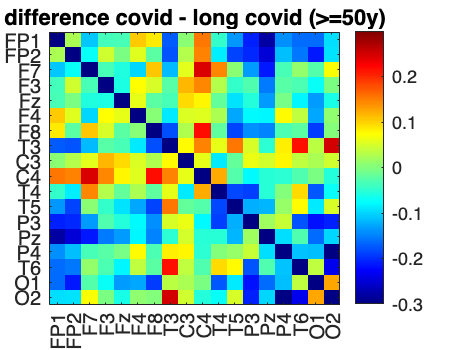

figure
GM_wplid_diff = squeeze(mean(GM_wplid_cov))-squeeze(mean(GM_wplid_longcov2));
imagesc(squeeze(GM_wplid_diff(:,:,f_alpha_ind)))
colorbar
colormap jet
clim([-0.3 0.3])
xticks(1:18); xticklabels(label)
yticks(1:18); yticklabels(label)
title('difference covid - long covid (>=50y)')

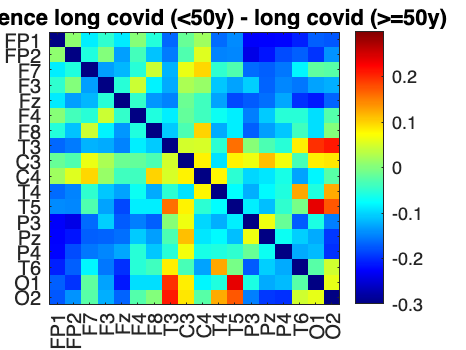

figure
GM_wplid_diff = squeeze(mean(GM_wplid_longcov1))-squeeze(mean(GM_wplid_longcov2));
imagesc(squeeze(GM_wplid_diff(:,:,f_alpha_ind)))
colorbar
colormap jet
clim([-0.3 0.3])
xticks(1:18); xticklabels(label)
yticks(1:18); yticklabels(label)
title('difference long covid (<50y) - long covid (>=50y)')

zval_2 = zeros(length(labels), length(labels)); % Preallocate for efficiency
for chan1 = 1:length(labels)
    for chan2 = 1:length(labels)
        % Accessing zval for each pair of labels
        if ~isfield(CON.stat(chan1,chan2), 'zval')
            warning('zval field does not exist for (%d,%d)', chan1, chan2);
        end
        if isempty(CON.stat(chan1,chan2).zval)
            warning('zval is empty for (%d,%d)', chan1, chan2);
        end
        if isfield(CON.stat(chan1,chan2), 'zval') && ~isempty(CON.stat(chan1,chan2).zval)
            zval_2(chan1,chan2) = CON1.stat(chan1,chan2).zval;
        end
    end
end



disp(CON1.stat(2,1)); % Check if this exists and has a zval field

       zval: 0.9850
    ranksum: 403.5000



disp(CON1.stat(2,1).zval); % Check if zval has a value

    0.9850



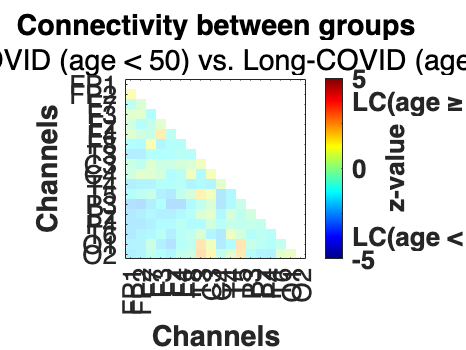

% longcov<50y vs. longcov>=50y
% longcov 1 vs. longcov 2
figure
zval_2(isnan(zval_2))=0;
alpha_array = (zval_2<-1.96) | (zval_2>1.96);
alpha_array_1 = 0.3*double(~alpha_array);
alpha_array_2 = double(alpha_array);
alpha_array = alpha_array_1 + alpha_array_2;
alpha_array = alpha_array - triu(alpha_array);

imagesc(zval_2,'AlphaData',alpha_array)
axis square
xlabel("Channels","FontSize",13,"FontWeight","bold"); ylabel("Channels","FontSize",13,"FontWeight","bold")
caxis([-3.92 3.92]);

colormap(jet)
c=colorbar();
c.Label.String = ["z-value"];
c.Label.Position(1) = 3;
c.FontSize = 13;
c.FontWeight= "bold";
c.Ticks = [-3.92,-2.94,-1.96, 0, 1.96, 2.94, 3.92];
c.TickLabels = [{int2str(-5),'LC(age < 50) > LC(age ≥ 50)','','0','','LC(age ≥ 50) > LC(age < 50)',int2str(5)}];

xticks(1:length(labels))
xticklabels(labels)     
yticks(1:length(labels))
yticklabels(labels)
title("Connectivity between groups")
subtitle("Long-COVID (age < 50) vs. Long-COVID (age ≥ 50)")
% subtitle("(Absolute dWLPI)","FontSize",13)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',13)